# 11 Аналоговая модуляция

**Цель:** познакомится с моделированием разных видов аналоговых модуляций

На прошлых занятиях мы строили разные модели механических систем и изучали их свойства, учились создавать модели и проводить моделирование. На следующих двух занятиях мы попытаемся при помощи моделирования изучить новую тему, а именно передача информации, посколько модели помогают не только в реальных задачах, но и в исследовании новых областей знаний, которые сложно изучить без такого инструмента, как моделирование.

## 1 Передача аналоговой информации

Передача информации на расстоянии была одной из важнейших проблем на протяжении всего развития цивилизации. Многие важные этапы развития цивилизации связаны с прорывами в области распространения, хранения и передачи информации. Такие этапы даже иногда называются информационными революциями. Одним из важнейших этапов было изобретение телеграфа, телефона и радио. Одна из основных задач, которую они решали, это передача голосовых сообщений (звука) на дальние растояния.

И поскольку в начале XX-века еще не появилась компьютеров и представить информацию в цифровом виде еще невозможно, передача информации осуществлялась в аналоговом виде. Это означало, что звук напрямую воздействовал на распространяемый радиосигнал. На этом занятии мы разберемся какие принципы лежали в основе этого процесса.

## 2 Что такое модуляция?

Для передачи сигнала на расстонии используются электромагнитные волны. Звуковые колебания сначала при помощи микрофона преобразовывавается в аналоговый сигнал напряжения и после некоторых преобразований подаётся на антенну. Передающая антенна излучает этот сигнал в виде электромагнитных колебаний, электромагнитные колебания распространяются в пространстве и воздействуют на принимающую антенну и после чего могут быть при помощи динамика преобразованы в звуковые колебания. На первый взгляд, может показаться, что можно напрямую подать колбеания с мирокофона на антенну, но в радио применяется другой подход.

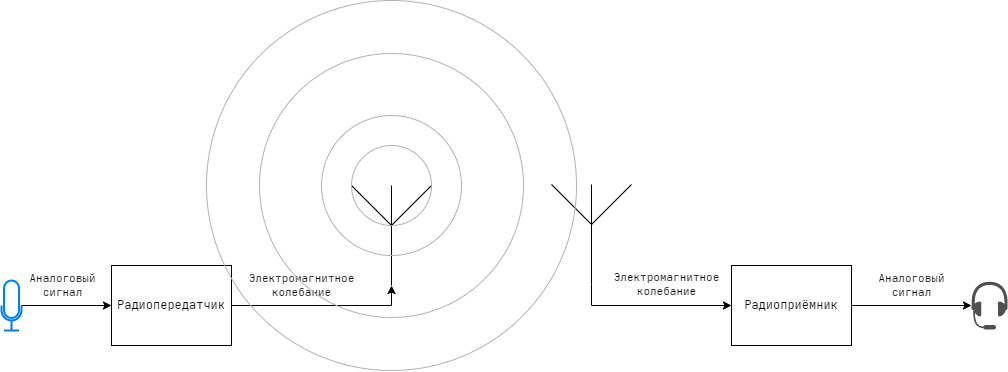

Применяется принцип модуляции сигнала. **Модуляцией** называется процесс изменения параметров одного сигнала, называемого **модулируемым** (или несущим), при помощи другого сигнала называемого **модулирующим** (или информационным)

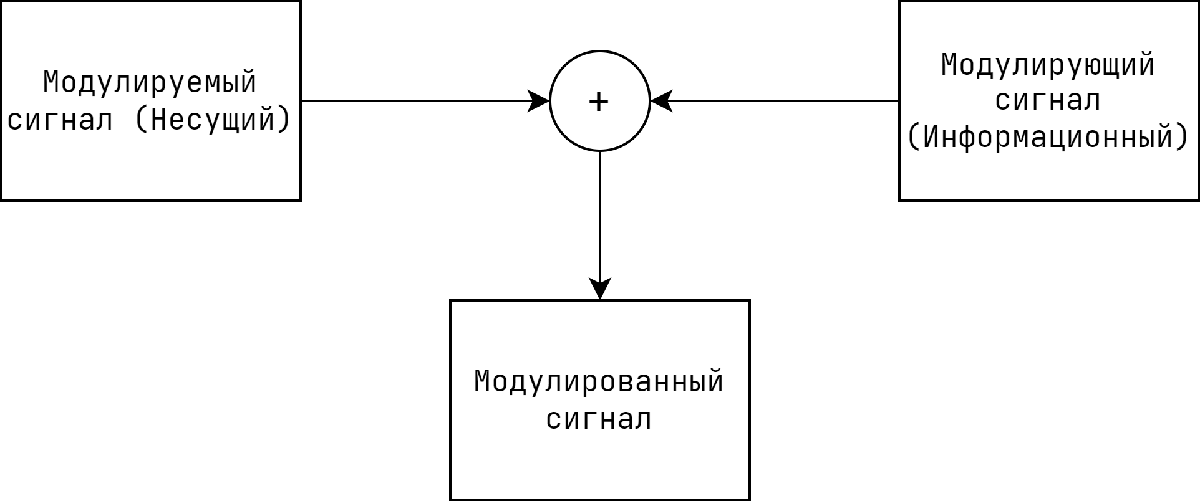

Информационный звуковой сигнал модулирует другое электромагнитное колебание на высокой (выше, чем частота информационного сигнала) частоте. Такое колебание называется несущим сигналом. Этот подход позволяет во-первых создать несколько каналов данных, а значит на разных частотах могут передоваться разные информационные сигналы и не влиять друг на друга. Во-вторых, параметры антенны напрямую связаны с длиной волны сигнала, и чем больше длина волны электромагнитного колебания, тем больше должна быть антенна, которая его передаёт и принимает. И, наконец, это позволяет защитить сигнал от воздействия источников, которые генерируют электромагнитные колебания на низких частотах, например, таким может быть наша электрическая сеть, которая работает на частоте 50Гц.

Несущий сигнал может иметь разную природу, но в аналоговой радиотехнике это обычно гармоническое колебание напряжения на некоторой основной частоте. Такое колебание выглядит следующим образом:


$$u_c = A\sin(\omega_0t+\varphi_0)$$


Мы можем влиять либо на амплитуду данного колебания, либо на фазу внутри функции синуса, меняя ее мнговенную частоту или мнгновенную фазу. Основная частота несущего колебания $\omega_0$ является основным параметром данного сигнала.

Из того, как мы можем менять параметры несущего колебания выходит, что есть три основных типа аналоговой модуляции:

- амплитудная -- изменение амплитуды сигнала

- фазовая -- изменение мнговенной фазы сигнала

- частотная -- изменение мнгновенной частоты сигнала

## 3 Виды модуляций

### 3.1 Амплитудная модуляция (AM)

Самый простой вид модуляции это амплитудная. Принцип состоит в том, что мы отклоняем амплитуду несущего колебания от исходного значения в зависимости от амплитуды информационного колебания.

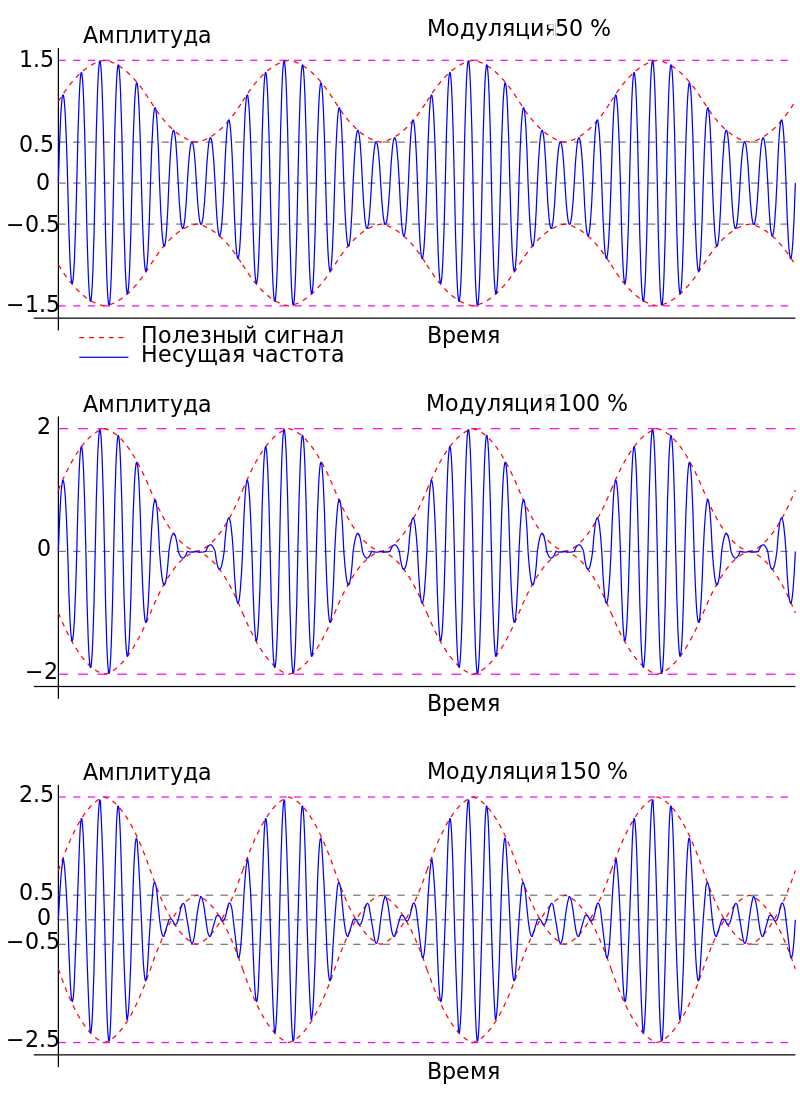

Величина отклонения амплитуды, это отношение максимальной и минимальной амплитуды сигнала, называется глубиной модуляции, или порядком модуляции. На рисунке выше можно увидеть, как разная глубина модуляции влияет на модулированный сигнал. 

Выразим приницп амплитудной модуляции в виде формулы:


$$u_{am}(t) = u_c(t)\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right]
\\
m = \frac{A_{max} - A_{min}}{A_{max}+A_{min}} \leq 1$$


где:

- $u_m(t)$ -- модулирующий сигнал 

- $u_c(t)$ -- модулируемый сигнал

- $m$ -- коэффициент модуляции

Как видно из формулы, мы просто добавляем наше информационное колебание к несущему с некоторым коэфиициентом.

Давайте в виде скрипта опишем процесс модуляции в случае, если наше информационное колебание является обычным однотональным колебанием.

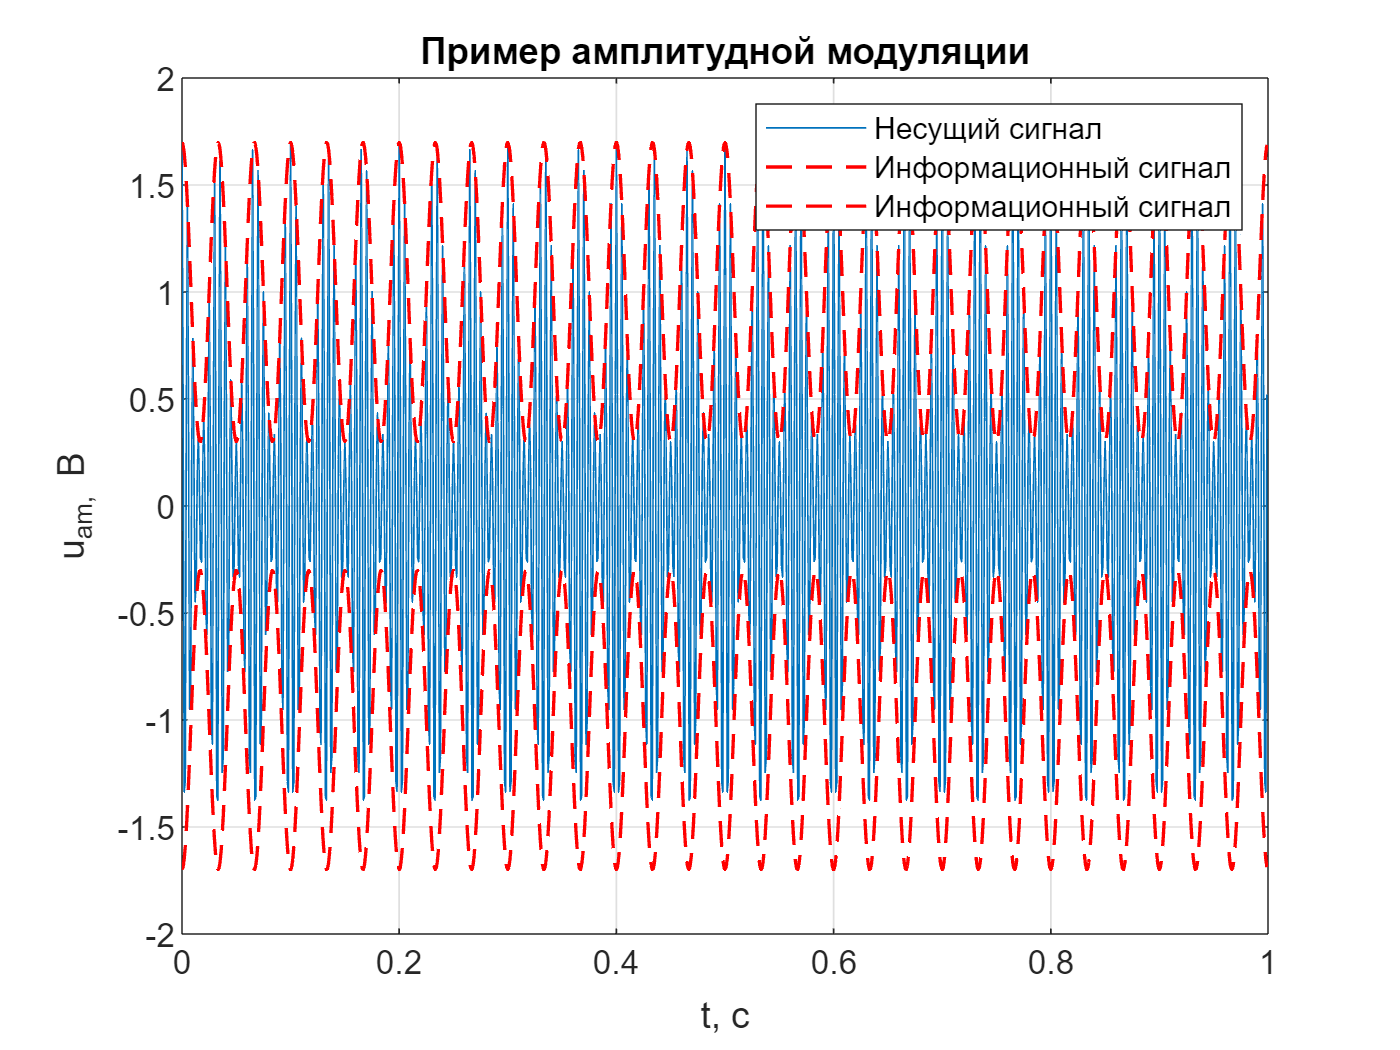

close all;

%% Параметры временной сетки
dt = 0.001;
t = 0 : dt : 1-dt;

%% Расчёт несущего сигнала
A_c = 1;
f_c = 200;
w_0 = 2 * pi * f_c; % Частота несущего сигнала
u_c = A_c * cos(w_0*t); % Несущий (модулируемый) сигнал

%% Расчёт информационного сигнала
f_m = 30;
w_m = 2 * pi * f_m; % Частота информационного сигнала
A_m = 1;
u_m = A_m * cos(w_m*t); % Информационный (модулирующий) сигнал

%% Расчёт модулированного сигнала
m = 0.7; % Порядок модуляции
u_am = u_c .* (1 + m * (u_m / max(u_m))); % Модулированный сигнал


%% Построение графика
figure();
plot(t, u_am, 'DisplayName','Несущий сигнал');
hold all;
plot(t, (1 + m*u_m), 'r--', 'DisplayName', 'Информационный сигнал', 'LineWidth',1);
plot(t, (-m*u_m - 1), 'r--', 'DisplayName', 'Информационный сигнал', 'LineWidth',1);
title('Пример амплитудной модуляции');
xlabel('t, с');
ylabel('u_am, В');
legend();
grid('on');

Можете попробовать поменять порядок модуляции и посмотреть как изменяется сигнал.

Рассмотрим спектр амплитудного модулированного (АМ) сигнала разложив модулированный сигнал на независимые по частоте компонеты:


$$u_{am} = A_0\cos(\underbrace{\omega_0}_1t) + \frac{A_m}{2} \cos(\underbrace{(\Omega-\omega0)}_2) + \frac{A_m}{2} \cos(\underbrace{(\Omega+\omega0)}_3)$$


Теперь построим спектр нашего смоделированного сигнала

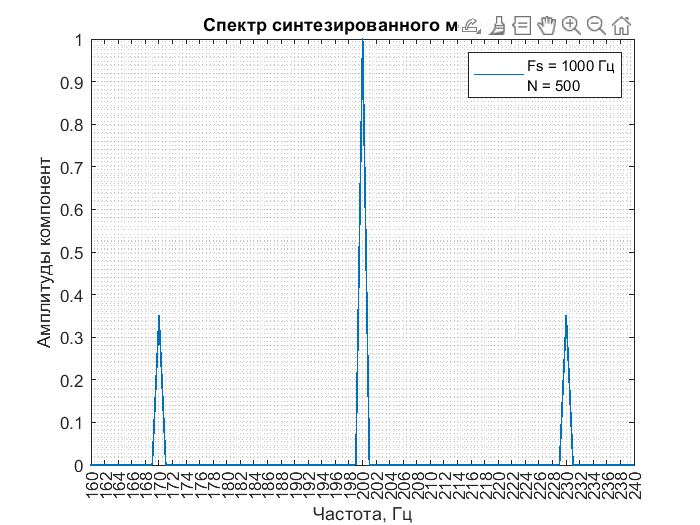

Fs = 1 /dt;
df = Fs / length(u_am);
freqs = 0 : df : (Fs/2-df); % Берем только половину спектра
u_am_fft = fft(u_am);
u_am_fft = abs(u_am_fft(1:length(freqs)))/(length(freqs));
f = figure();
plot(freqs,u_am_fft,'LineWidth',1);
% xlim([0, Fs/2]);
set(gcf,'Visible','on');
grid("minor");
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
xticks([0: 2 :(Fs/2)-df])
xlim([160 240]);
title('Спектр синтезированного меандра');
legend_text = sprintf("Fs = %d Гц\nN = %3.0f", Fs, length(freqs));
legend(legend_text);

Как видно, на спектре действительно получилось три компоненты. Компонента на центральной частоте и две боковые на расстоянии частоты информационного сигнала

### 3.2 Фазовая модуляция (PM)

Амплитудная модуляция имеет слишком большую подверженность шумам. Поскольку некотоыре шумы имееют аддитивную природу они влияют на изменение именно амплитуды сигнала, а значит будут влиять на наш информационный сигнал. Для решения этой проблемы используется подход, в котором модулируется не амплитуда, а фаза сигнала. Таким аддитивный шум оказывает меньшее влияние.

Запишем полуную фазу несущего колебания:


$$\Psi(t) = \omega_0t+\varphi(t)$$


Явно видно, что можно менять дополнительную фазу $\varphi(t)$ в зависимости от информационного сигнала $u_m(t)$ с некоторым коэффициентом m, который называется девиацией фазы:


$$\Psi(t) = \omega_0t+mu_m(t)$$


В конечном итоге, получится следующий вид модулированного сигнала:


$$u_{pm}(t) = A_0\cos(\omega_0t+mu_m(t))$$


### 3.3 Частотная модуляция (FM)

Чаще для улучшения характеристик сигнала используется частотная модуляция. Важно отметить, что данные виды модуляции усложняют передатчик и приёмник сигнала. Если рассмотреть производную полной фазы, то получим **мгновенную частоту** сигнала:


$$\omega(t) = \frac{d\Psi}{dt} = \omega_0 + \omega_du_m(t)$$


Здесь видно, что информационный сигнал влияет именно на мгновенную частоту. Чтобы получить полную фазу сигнала необходимо проинтегрировать данное выражение:


$$\Psi(t) = \int{\omega(t)dt} = \omega_0t+\omega_d\int{u_m(t)dt}+const$$


В конечном итоге получим такой вид модулированного сигнала:


$$u_{fm} = A_0\cos\left(\omega_0t + \omega_d\int{u_m(t)dt}+const\right)$$


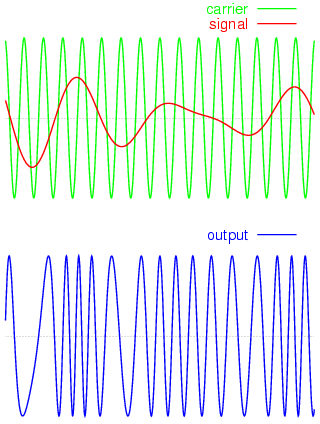

## 4 Демодуляция

Демодуляция это процесс обратный модуляции, в котором необходимо восстановить информационный сигнал из принятого модулированного. Зачастую процесс демодуляции гораздо сложнее, чем процесс модуляции. Поэтому в этом занятии мы расмотрим только то, как выполняется демодуляция в случае АМ.

Выполним математические преобразования необходимые при демодуляции. Домножим сигнал на сигнал на частоте несущей на передаче:


$$u_{am}(t) * \cos(\omega_0t)= u_c(t)*\cos(\omega_0t)\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right]

$$


Распишем формулу несущего колебания и применим тригонометрические преобразования понизив степень косинуса.


$$A_0*cos(\omega_0t)*\cos(\omega_0t)\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right] =
\\
= \frac{A_0}{2}\left(1+\cos(2\omega_0t)\right)\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right] =
\\
= \frac{A_0}{2}\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right] + \frac{A_0}{2}\cos(2\omega_0t)\left[1+ m \frac{u_m(t)}{|u_m(t)|_{max}}\right]
$$


Видно, что в выражении появляется два члена. Один из них зависит от удвоенной несущей частоты, а другой содержит в себе информационный сигнал. Выполним эти действия для сигнала и построим спектр

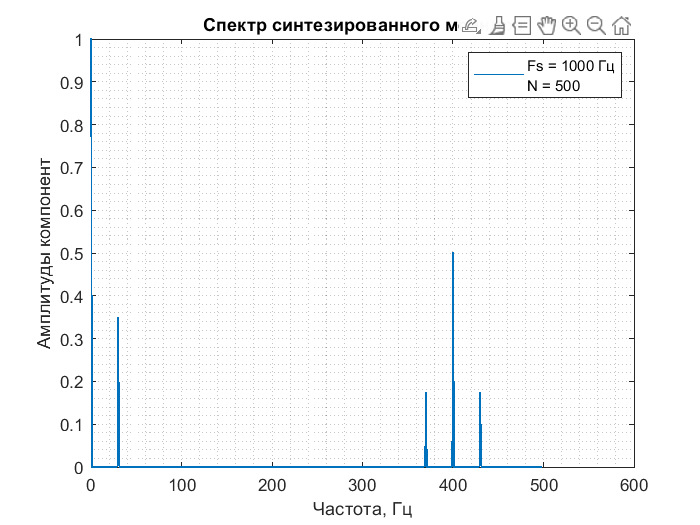

u_am_dem = u_am .* cos(w_0*t);

u_am_dem_fft = fft(u_am_dem);
u_am_dem_fft = abs(u_am_dem_fft(1:length(freqs)))/(length(freqs));
f = figure();
plot(freqs,u_am_dem_fft,'LineWidth',1);
% xlim([0, Fs/2]);
set(gcf,'Visible','on');
grid("minor");
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
% xticks([0: 2 :(Fs/2)-df])
xlim([0 600]);
title('Спектр синтезированного меандра');
legend_text = sprintf("Fs = %d Гц\nN = %3.0f", Fs, length(freqs));
legend(legend_text);

На спектре видно все компоненты сигнала, которые мы получили в тригонометрическом разложении. В нулевой частоте константа, которая не зависит от сигнала. На частоте 30Гц наш информационный сигнал. На удвоенной частоте несущей 400 Гц сигнал, который повторяет модулированный, но на больше частоте и деленный на два.

Осталось только каким-то образом убрать лишние сигналы. Постоянную компоненту нужно просто вычесть из сигнала. Сигнал на удвоенной частоте необходимо убрать при помощи фильтра нижних частот.

Фильтр нижних частот -- это такое устройство, которое пропускает частотный спектр ниже некоторой частоты, которую называют частотой среза, и подавляет частотный спектр на частоте выше частоты среза.

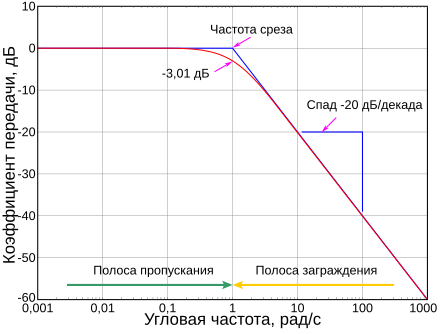

В задании вам предлогается использовать его для подавления сигнала на частотах выше частоты несущей.

## 5 Задание

### Задание 1. Амплитудный модулятор (+2 балла)

- Создать модель `am.slx`

- Создать подсистему `Генератор информационного сигнала`

- В этой подисистеме создать четыре блока `Sin Wave` c частотами **100, 80, 60, 40 Гц**, суммировать их и нормировать по амплитуде суммарный сигнал

- Подать нормированный сигнал на выход `Информационный сигнал`

- Создать подсистему `AM Модулятор` со входом `Модулирующий сигнал` и выходами `Модулированный сигнал` и `Модулируемый сигнал`

- Добавить в маску этой подсистемы параметры `Частота несущей`, `Порядок модуляции`

- Реализовать внутри этого блока формулу амплитдной модуляции

- Установить частоту несущей **300 Гц**

- Установить порядок модуляции **0.5**

- Подать `Информационный сигнал`, `Модулированный сигнал` и `Модулируемый сигнал` на `Scope`

- `Модулированный сигнал` преобразовать в цифровой сигнал при помощи блока `Zero-Order Hold`

- Параметр `Sample Time` должен быть равен **1e-3**

- Полученный сигнал подать на блок `Spectrum Analyzer`

- Запустить модель с `Stop Time` 10 секунд

- Проанализировать полученный спектр

### Задание 2. Фазовый модулятор (+3 балла)

- Создать модель `pm.slx`

- Cоздать подсистему `PM Модулятор` с такими же входами и выходами как у `AM Модулятор`

- Добавить в маску этой подсистемы параметры `Частота несущей`, `Девиация Фазы`

- Реализовать внутри этого блока формулу фазовой модуляции модуляции

- ВАЖНО! При построении не получится использовать блок Sin Wave, так как нужно влиять на фазу сигнала. Поэтому нужно рассчитывать всю фазу для функции синуса. Чтобы получить время воспользуйтесь блоком `Clock`

- Подать `Модулированный сигнал` на тот же `Scope`

- Также исследовать спектр `Модулированного сигнала` при помощи блока `Spectrum Analyzer`

### Задание 3. Частотный модулятор (+3 балла)

- Создать модель `fm.slx`

- Cоздать подсистему `FM Модулятор` с такими же входами и выходами как у `AM Модулятор`

- Добавить в маску этой подсистемы параметры `Частота несущей`, `Девиация Частоты`

- Реализовать внутри этого блока формулу частотной модуляции модуляции

- Подать `Модулированный сигнал` на тот же `Scope`

- Также исследовать спектр `Модулированного сигнала` при помощи блока `Spectrum Analyzer`

### Задание 4. Амплитудный демодулятор (+2 балла)

- В файле `am.slx` cоздать подсистему `AM Демодулятор` с входом `Модулированный сигнал` и `Демодулированный сигнал`

- Добавить в маску этой подсистемы параметры `Частота несущей`, `Порядок модуляции`

- Реализовать внтури этой подсистемы алгоритм амплитудной демодуляции

- В качестве фильтра нижних частот использовать блок `Analog Filter Design`. Порядок фильтра установить в значение 16, значение частоты установить в значение основной частоты несущего колебания

- Подать демодулированный сигнал на `Scope` и убедится, что демодулированный сигнал совпадает по форме с информационным